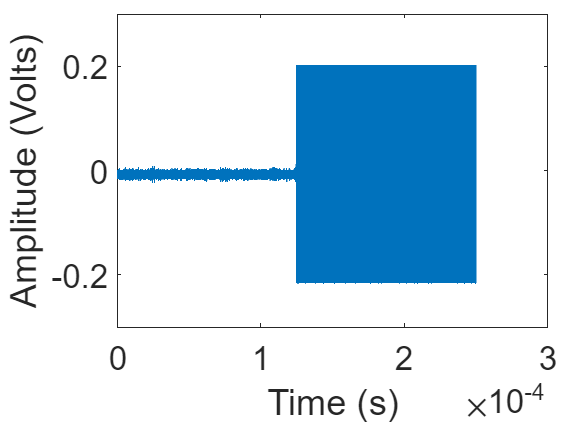


signal=load('BEEBEERUN_0000100002.mat'); % Load the raw signal

% Plot with x-axis in seconds and y-axis in Volts..font 15
h = plot(double(signal.Channel_1.Data)*6.581e-06); % scaling the voltage using a scale factor of 6.581e-06
aH = ancestor(h,'axes');
x_axis = get(h,'XData');
new_x = x_axis .* 5.0000e-11;
new_y = get(h,'Ydata');
delete(h);
plot(aH,new_x,new_y)
set(gca,'fontsize',18)
xlabel('Time (s)')
ylabel ('Amplitude (Volts)')
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
ylim([-0.3 0.3])